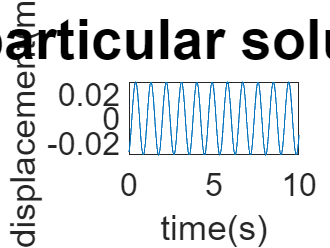

% © 2022 2018100778 최동욱 기계공학과 <ch3044637@khu.ac.kr>
% 2022-1학기 기계진동 term_project
% 자동차의 진동의 특수해에 대한 시간응답 해석해

clear; clc;

% initial condition
m = 800; k = 4e4; c = 2e3; v = 20;
l = 0.005; hour2sec = 3600; A = 0.01;
t = 0:0.01:10;

% natural frequency, driving frequency, damping ratio
Wn = sqrt(k/m);
Wb = v*2*pi/(l*hour2sec);
zeta = c/(2*sqrt(k*m));

% particular solution solved by analytic method
seta1 = atan(2*zeta*Wn*Wb/(Wn^2-Wb^2));
Xp1 = 2*zeta*Wn*Wb*A/sqrt((Wn^2-Wb^2)^2+(2*zeta*Wn*Wb)^2)*cos(Wb*t-seta1);
Xp2 = Wn^2*A/sqrt((Wn^2-Wb^2)^2+(2*zeta*Wn*Wb)^2)*sin(Wb*t-seta1);
Xp = Xp1 + Xp2;

% plot
plot(t, Xp)
set(gca,'FontSize',24);
title('particular solution','FontSize',42,'FontWeight','bold');
xlabel('time(s)');
ylabel('displacement(m)');